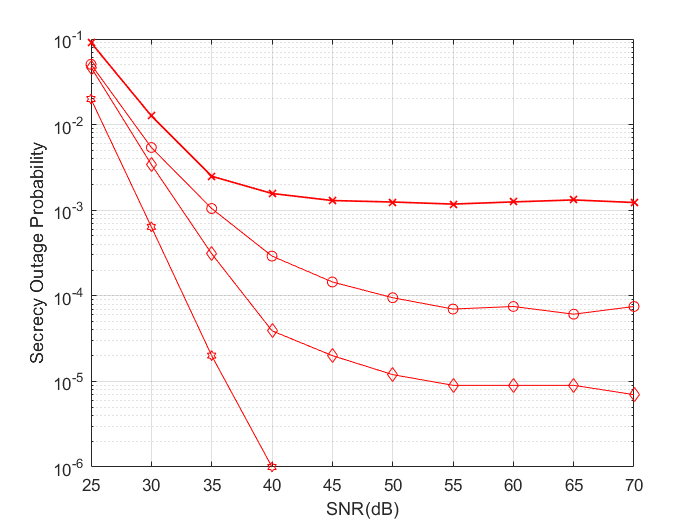

%中继信任度对安全性能的影响
x=[25;30;35;40;45;50;55;60;65;70];
pro=[0.050633,0.005401,0.001047,0.000291,0.000145,9.5e-05,7.0e-05,7.5e-05,6.1e-05,7.5e-05];
NotTrustProbability=[0.09083,0.012658,0.002495,0.001568,0.001297,0.001246,0.001179,0.00125,0.001318,0.00123];
FullTrustProbability=[0.018021,0.001204,0.000156,0.00006,0.000031,0.000027,0.000022,0.000027,0.000024,0.000024];
Two_Probability=[4.6802e-2,3.416e-3,3.1e-4,3.9e-5,2e-5,1.2e-5,9e-6,9e-6,9e-6,7e-6];
three_Probability=[1.989e-2,6.39e-4,2e-5,1e-6,0,0,0,0,0,0];

semilogy(x,NotTrustProbability,'-xr','LineWidth',1);
hold on;
%信任度为0.5，0.8和0.6

%semilogy(x,FullTrustProbability,'-*r','LineWidth',1);
%hold on;
% 信任度为1,0.4和0.3

semilogy(x,pro,'-or');%红色圆-三中继
hold on;
%信任度为1,0.8和0.6

semilogy(x,Two_Probability,'-dr');
hold on;
%信任度为1.0，1.0和0.6

semilogy(x,three_Probability,'-hr');
hold on;
%信任度1,1和1

xlabel('SNR(dB)');
ylabel('Secrecy Outage Probability');
grid on